**1 a) Read and show the image.**

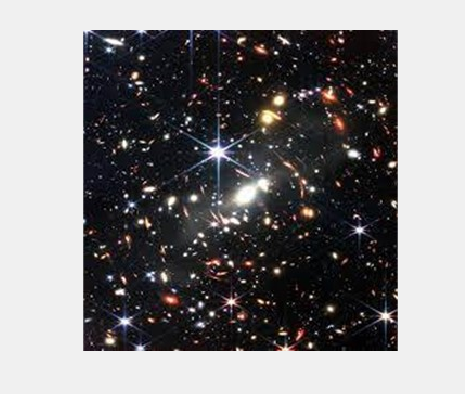

p1 = imread('Picture1.jpg');
imshow(p1)

**1 b)Show the matrix form of the image.**

p1

p1 = 296×290×3 uint8 array
p1(:,:,1) =

   227   235   243   243   251   247   213   131    74    60    45    36    35    40    38    31    19    20    19    17    20    23    24    24    25    27    28    22    21    20    21    18    30    46    33    25    30    55    71    30    32    39    25    19    39    49    52    64    74   109   156   192   222   245   236   204   155   124    93    69    44    32    31    11    23    43    44    14    15    71   108    95    23    20    55    94   102    68    23    13    19    23    18    13    16    18    16    22    30    29    27    20    22    25    22    14     5    26    81   119    87    35    23    26    33    30    26    20    38    73    73    31     5    30    33    22    31    33    21    10    28    54    78    82   104    88    51    35    26    26    34    32    19    21    28    22    14    19    30    34    60    50    30    27    33    24    20    19    20    23    26    26    33    39    36    19    12    15    16    12

**1 c) Show the pixel information by hovering the cursor on the image.**

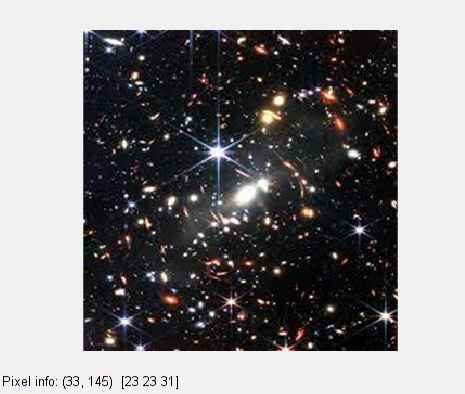

impixelinfo()

**1 d) Find the value of the pixel (10, 78)**

p1(10, 78)

ans = uint8
19

**1 e) Show the size of the image.**

size(p1)

ans =    296   290     3


**1 f) Show the all the information of the image.**

imfinfo('Picture1.jpg')

ans = struct with fields:
           Filename: 'D:\Education\#CSE_438\Lab_Project\Picture1.jpg'
        FileModDate: '20-Oct-2022 19:53:27'
           FileSize: 34263
             Format: 'jpg'
      FormatVersion: ''
              Width: 290
             Height: 296
           BitDepth: 24
          ColorType: 'truecolor'
    FormatSignature: ''
    NumberOfSamples: 3
       CodingMethod: 'Huffman'
      CodingProcess: 'Sequential'
            Comment: {}


**2 a)	Read and show all three types of images (RGB, Grayscale, and Indexed).**

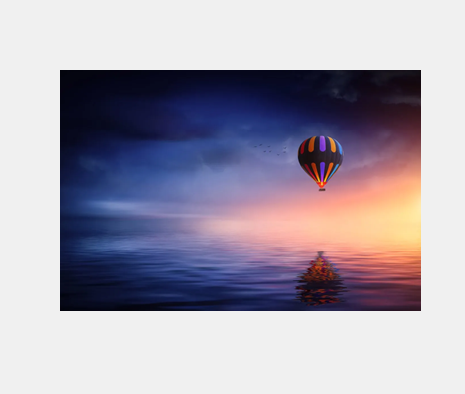

r = imread('Picture2.png');
g = rgb2gray(imread('Picture3.jpg'));
x = imread('Picture4.png');
[i,imap] = rgb2ind(x, 255);

imshow(r)

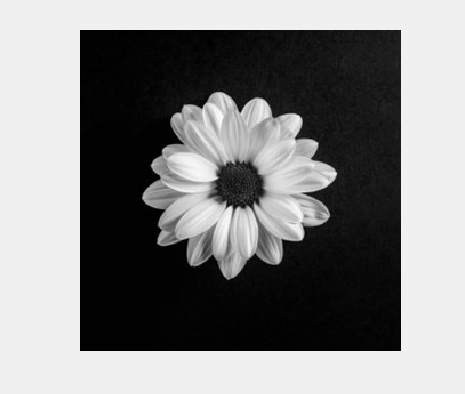

%impixelinfo()
imshow(g)

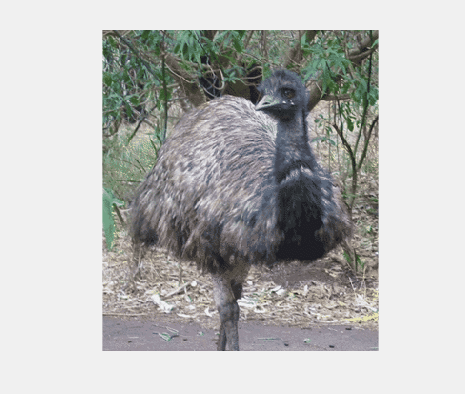

%impixelinfo()
imshow(i,imap)

%impixelinfo()

%r(50,100,:)
%g(50,100,:)
%i(50,100,:)

**2 b) Turn the RGB image to Grayscale image.**

r2g = rgb2gray(r);
imshow(r)

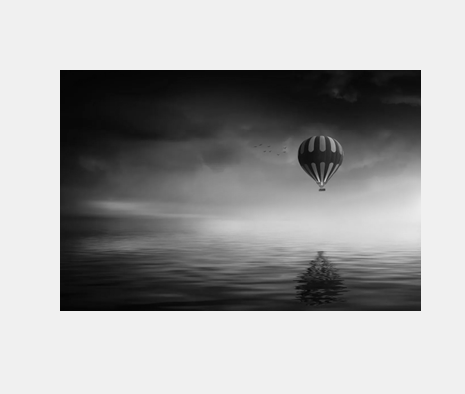

imshow(r2g)


%r2g(50,100,:)

**2 c) Turn the Indexed image to Grayscale image**

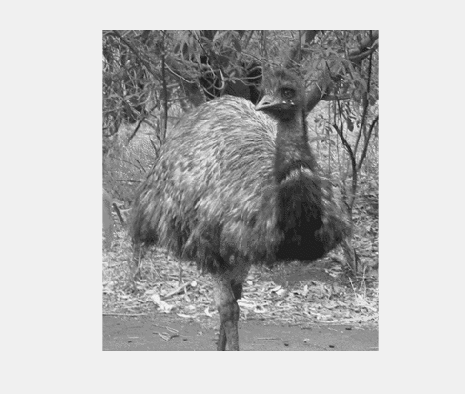

i2g = ind2gray(i,imap);
imshow(i2g)

**2 d) Turn the Indexed image to RGB image.**

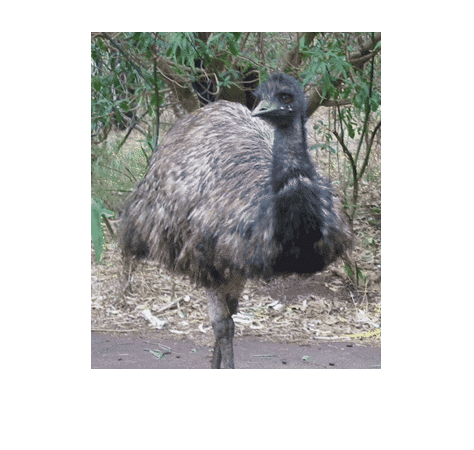

i2r = ind2rgb(i, imap);
imshow(i2r)

**2 e) Convert the Grayscale image to a Binary image.**

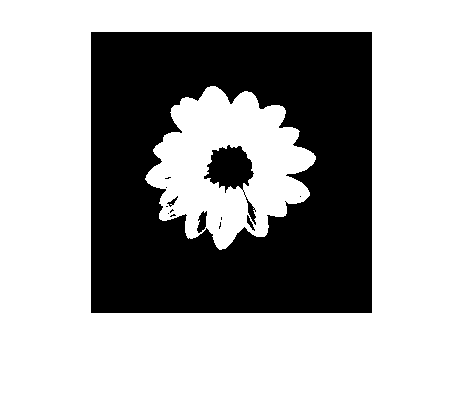

%bin = (g/255);
%imshow(bin);

BW = im2bw(g,0.4);
imshow(BW)


%impixelinfo()

**2 f) Show the inverted form of that Binary image.**

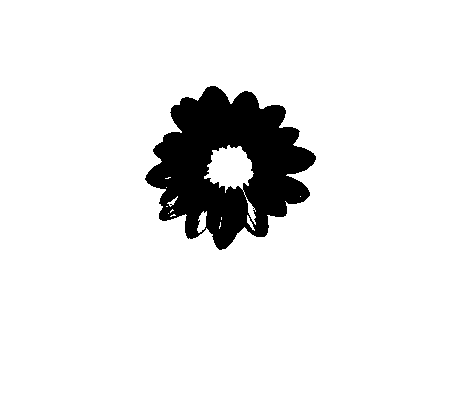

inv = imcomplement(BW);
figure, imshow(inv)


%impixelinfo()

**2 g)	Show the histogram of the Grayscale image.**

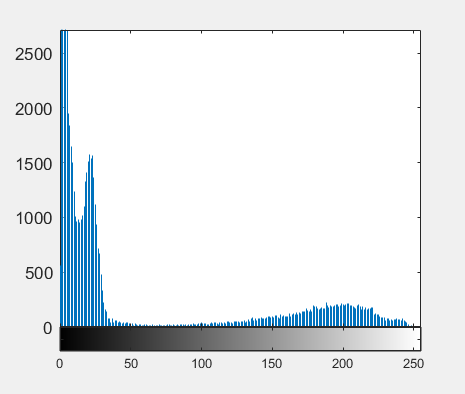

imhist(g)

**2 h) Invert the RGB image.**

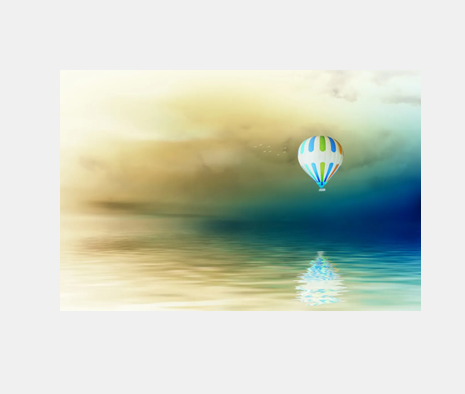

invert = imcomplement(r);
imshow(invert)

**2 i) Blur the RGB image.**

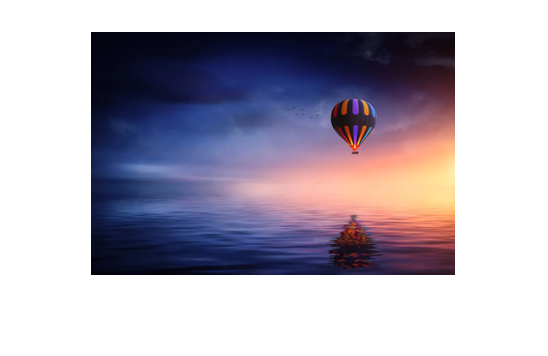

rgbImage = im2double(r);
windowSize = 15;
avg3 = ones(windowSize) / windowSize^2;
figure, imshow(rgbImage)

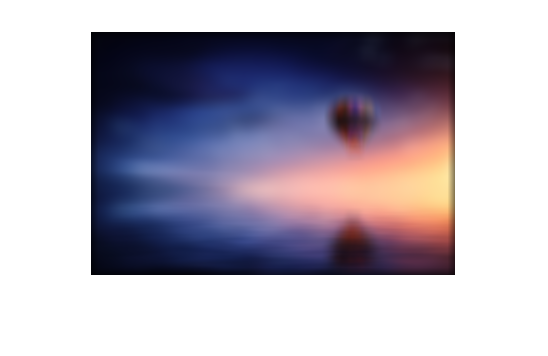

blurredImage = imfilter(rgbImage, avg3, 'conv');
figure, imshow(blurredImage)

**3. Create a complete black image of size 256 X 256.**

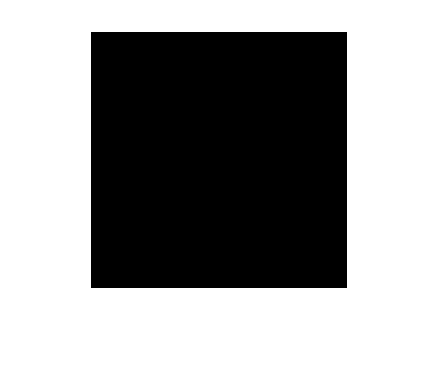

img1 = uint8(zeros(256,256));
imshow(img1)

**4. Create a complete white image of size 256 X 256.**

img2 = uint8(255*ones(256,256));
imshow(img2)

**5. Adjust the contrast of the following image.**

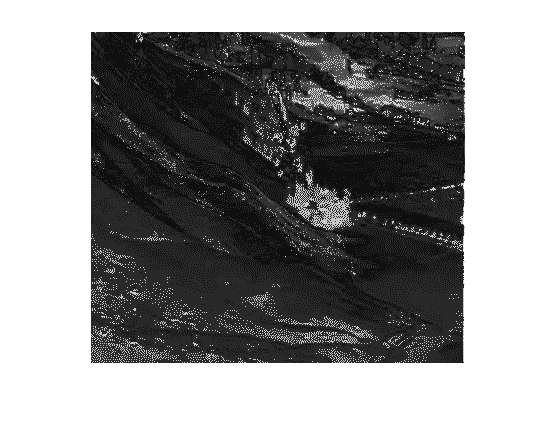

pic = imread("Picture5.png");
p5 = imadjust(pic,[0 0.8],[]);
imshow(p5)

**6. Brighten the following image**

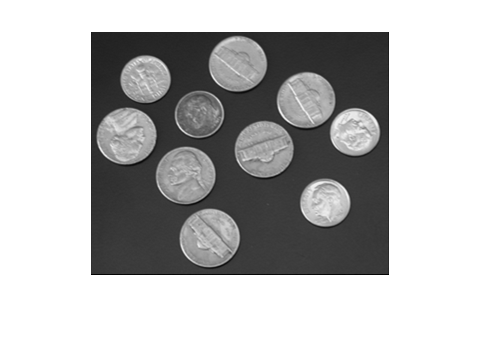

pic7 = imread('Picture7.png');
imshow(pic7)

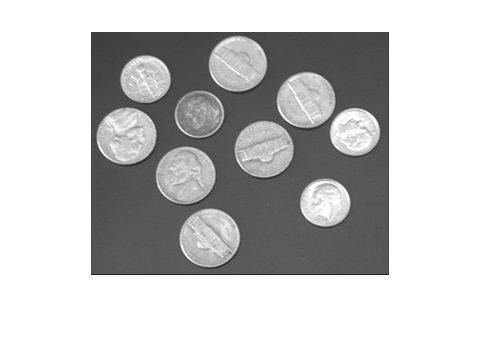

brigtherI = pic7+30;
imshow(brigtherI)

**7. Quantize the Grayscale image by 8 levels.**

pic7 = imread('Picture7.png');
imshow(pic7)

thresh = multithresh(pic7,7);
valuemax = [thresh max(pic7(:))]

valuemax = 1×8 uint8 row vector
    32    51    88   125   153   176   199   240


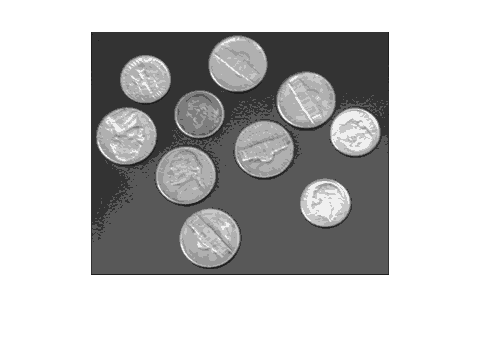

[quant8,index] = imquantize(pic7,thresh,valuemax);
imshow(quant8)